% cross section at spar location
h = 0.2 % m
b = 0.2 % m

t_skin = 0.5e-3




syms x n m f 

Axial_1 = 


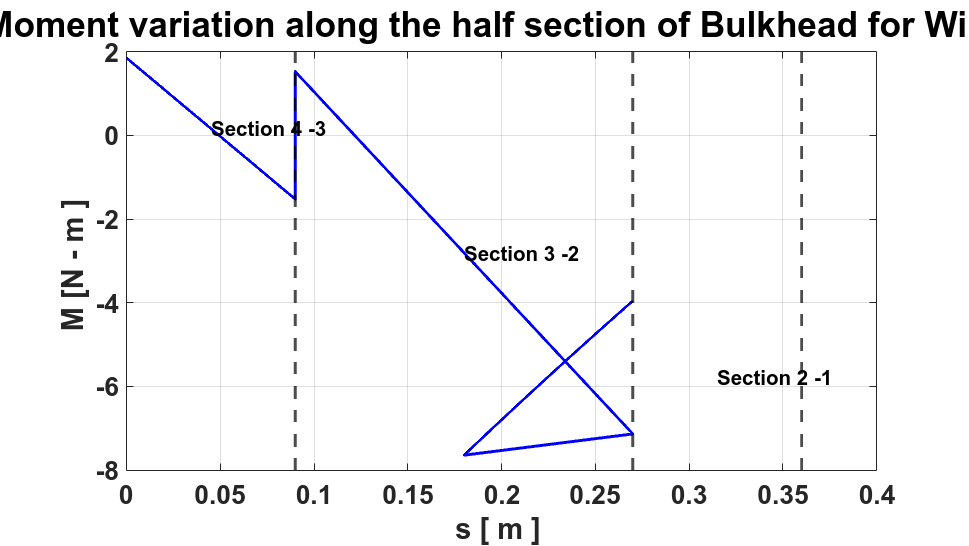

syms v f m x s
q = -12.534* x .^2 + 2.2543* x + 44.4996;
Axial (1) = f - 744.4* s .^2;
Shear (1) = -v ;
Moment (1) = m + v * s ;
Axial (2) = -v + 2145* s .^3 - 579.16* s .^2 - 148.89* s ;
Shear (2) = -f + 6.03;
Moment (2) = ( - m - 0.09* v + f * s - 6.03* s );
Axial (3) = -f + 6.03 - 744.44* s .^2 + 134* s ;
Shear (3) = v - 5.04 + int (q ,x ,0 , s ) - 9.81* s ;
Moment (3) = m + v *(0.09 - s ) - 0.18* f - 14.786 + 1.09 + 5.04* s - int ( q *( s - x ) ,x ,0 , s ) + 0.5*9.81* s ^2;
%%
U = var (1) ;
E = 70e9 ;
I = (0.09^3*0.0005) /3 + (0.09*0.0005^3) /12;
A = 4*0.09*0.0005;
As = (10*0.09*0.0005) /3;
b = [1 ,2 ,1]*0.09;
G = 26e9 ;
for i = 1:3
U = U + (1/( E * I *2) ) * int ( Moment ( i ) ^2 ,s ,0 , b ( i ) ) + (1/(2* E * A) ) * int ( Axial ( i ) ^2 ,s ,0 , b ( i ) ) + (1/(2* G * As ) ) * int ( Shear ( i) ^2 ,s ,0 , b ( i ) ) ;
end
dU (1) = diff (U , f ) == 0;
dU (2) = diff (U , v ) == 0;
dU (3) = diff (U , m ) == 0;
sol = solve ( dU ,[ f ,v , m ]) ;
solution = double ([ sol .f , sol .v , sol . m ]) ;
add = [0 , b (1) ,b (1) + b (2) ];
add2 (1) = 0;
for i = 1:3
    s_vec = linspace(0,b(i),1000);

    M_temp = subs(Moment(i),[f,v,m], ...
        [solution(1),solution(2),solution(3)]);

    m_sub(1+(i-1)*1000:i*1000) = double(subs(M_temp,s,s_vec));

    add2(i+1) = m_sub(i*1000);

    x_sub(1+(i-1)*1000:i*1000) = add(i) + s_vec;
end

figure ( 'units' , 'normalized' , 'outerposition' ,[0 0 1 1])
plot ( x_sub , m_sub , Color = 'blue' , LineWidth =2)
xline (0.09 , LineWidth =2 , LineStyle = '--' , Color = 'black')
xline (0.27 , LineWidth =2 , LineStyle = '--' , Color = 'black')
xline (0.36 , LineWidth =2 , LineStyle = '--' , Color = 'black')
text (0.045 , m_sub (500) , 'Section 4 -3' , 'FontSize' , 14 , 'FontName', 'Helvetica' , 'FontWeight' , 'bold')
text (0.18 , m_sub (1500) , 'Section 3 -2' , 'FontSize' , 14 , 'FontName', 'Helvetica' , 'FontWeight' , 'bold')
text (0.315 , m_sub (2500) , 'Section 2 -1' , 'FontSize' , 14 , 'FontName' , 'Helvetica' , 'FontWeight' , 'bold')
set ( gca , 'FontSize' , 18 , 'FontName' , 'Helvetica' , 'FontWeight' , 'bold') ;
grid on
xlabel ( 's [ m ] ') ;
ylabel ( 'M [N - m ] ') ;
title ( 'Moment variation along the half section of Bulkhead for Wing ' , 'FontSize' , 24 , 'FontName' , 'Helvetica' , 'FontWeight' , 'bold') ;

%%
sigma_all = (193e6 ) /(2.5*1.5*1.5*1.5) ;
m_max = max ( abs ( m_sub ) ) ;
t = 0.001;
syms b
equa = ( b +1) /(( b +2) *((1/16) *(( b ^2+4) /( b +2) ) + 1/6) ) ;
b_mat = linspace (0 ,3 ,100) ;
for i = 1:100
solu ( i ) = double ( subs ( equa ,b , b_mat ( i ) ) ) ;
end